clc;
clear;
close all;

%All
% folderName = "../ALLProcessed/smallAll"
% folderName = "../ALLProcessed/mediumAll"
folderName = "/Users/gershikoral/Desktop/labproject/mono";


%Female
% folderName = "/Users/gershikoral/Desktop/labproject/gender/Female";
% folderName = "../MALEFEMALEProcessed/medium/FemaleAll"
%folderName = "../MALEFEMALEProcessed/short/FemaleAll"

%Male
% folderName = "/Users/gershikoral/Desktop/labproject/gender/Male";
% folderName = "../MALEFEMALEProcessed/medium/MaleAll"
%folderName = "../MALEFEMALEProcessed/short/MaleAll"


normalizeMethod = "range";
rangeValues = [0,1];

folder = fullfile(matlabroot,'toolbox','audio','samples');
ads = audioDatastore(folderName,"IncludeSubfolders",true, "LabelSource","foldernames");

[filenames,~] = cellfun(@(x)fileparts(x),ads.Files,'UniformOutput',false);
filenames = (string(filenames));
wordSplit = split(filenames,"/");
segmentation = wordSplit(:,end);


ads.Labels = categorical(segmentation);

clear folderName filenames wordSplit segmentation

trainRatio = 0.6;
validationRatio = 0.25;
testRatio = 1-trainRatio-validationRatio;
shuffle(ads);
[train,validation,test] = splitEachLabel(ads,trainRatio,validationRatio,testRatio);

tallTrain      = tall(train);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 2).


tallValidation = tall(validation);
tallTest = tall(test);


clear trainRatio validationRatio testRatio 

%Matlab feature extraction occurs here
[~,adsInfo] = read(ads);
fs = adsInfo.SampleRate;
win = hamming(round(0.03*fs),"periodic"); 
%Produces an overlap length of 15ms --> 50% of the original
overlapLength = round(0.015*fs);


afe = audioFeatureExtractor( ...
    'Window',       win, ...
    'OverlapLength',overlapLength, ...
    'SampleRate',   fs, ...
    "pitch",true,...
    "harmonicRatio", true);

%Extract features
trainFeatures       = cellfun(@(x)extract(afe,x),tallTrain,"UniformOutput",false);
validationFeatures =cellfun(@(x)extract(afe,x),tallValidation,"UniformOutput",false);
testFeatures =cellfun(@(x)extract(afe,x),tallTest,"UniformOutput",false);

%Normalise Features
trainFeaturesNormed       = cellfun(@(x)normalize(x,normalizeMethod,rangeValues),trainFeatures ,"UniformOutput",false);
validationFeaturesNormed= cellfun(@(x)normalize(x,normalizeMethod,rangeValues),validationFeatures ,"UniformOutput",false);
testFeaturesNormed= cellfun(@(x)normalize(x,normalizeMethod,rangeValues),testFeatures ,"UniformOutput",false);
YTrain = train.Labels;
YValidation = validation.Labels;
YTest = test.Labels;

XTrainData = cellfun(@transpose,trainFeaturesNormed ,'UniformOutput',false);
XTrainData = gather(XTrainData);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 2 min 41 sec
Evaluation completed in 2 min 41 sec


XValidationData = cellfun(@transpose,validationFeaturesNormed ,'UniformOutput',false);
XTestData = cellfun(@transpose,testFeaturesNormed,'UniformOutput',false);

XTestData = gather(XTestData);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 31 sec
Evaluation completed in 31 sec


XValidationData = gather(XValidationData);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 48 sec
Evaluation completed in 48 sec


Segmenting to the shortest 

numObservations = numel(XTrainData);
for i=1:numObservations
    sequence = XTrainData{i};
    %sequence = XValidationData{i};
    sequenceLengths(i) = size(sequence,2);
end

sequenceLengths = sort(sequenceLengths);
minSequence = sequenceLengths(1);

XValidationData  = cellfun(@(x) x(:,1:minSequence), XValidationData ,'uni',false);
XTrainData = cellfun(@(x) x(:,1:minSequence), XTrainData,'uni',false);
XTestData = cellfun(@(x) x(:,1:minSequence), XTestData,'uni',false);

inputSize = size(XTrainData{1,1},1);
numHiddenUnits = 11;
numClasses = 2;
maxEpochs = 100;
miniBatchSize = 65;
initialLearnRate = 0.0144;
drop = 0.2932;
l2reg = 0.0079;

layers = [ ...
    sequenceInputLayer(inputSize)
    gruLayer(numHiddenUnits,"OutputMode","last")
%     dropoutLayer(drop)
    batchNormalizationLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];
   
XValidationData = gather(XValidationData);

options = trainingOptions('sgdm', ...
    'GradientThreshold',1,...
    'ExecutionEnvironment','cpu', ...
    'L2Regularization',l2reg,...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'InitialLearnRate',initialLearnRate,...
    'SequenceLength','shortest', ... % Crops rather than padds
    'ValidationData',{XValidationData,YValidation}, ...
    'ValidationFrequency',50,... % The number of iterations between evaluations of validation metrics
    'Shuffle','every-epoch', ... % Shuffle the training data before each training epoch, and shuffle the validation data before each network validation. To avoid discarding the same data every epoch, set the 'Shuffle' value to 'every-epoch'.
    'Verbose',1, ... %produces a summary of training https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html#bu80qkw-3_head
    'VerboseFrequency',50,... %number of iterations between printing summary
    'Plots','training-progress');
   
net = trainNetwork(XTrainData,YTrain,layers,options);

|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:05 |       43.08% |       46.15% |       1.2719 |       1.1458 |          0.0144 |


|      25 |          50 |       00:00:23 |       63.08% |       57.69% |       0.6586 |       0.6820 |          0.0144 |


|      50 |         100 |       00:00:43 |       55.38% |       52.56% |       0.6890 |       0.6862 |          0.0144 |


|      75 |         150 |       00:01:02 |       64.62% |       57.69% |       0.6450 |       0.6763 |          0.0144 |


|     100 |         200 |       00:01:28 |       55.38% |       58.97% |       0.6770 |       0.6741 |          0.0144 |


|======================================================================================================================|


## Testing the model

XTestData = gather(XTestData);
YPred = classify(net,XTestData, ...
    'MiniBatchSize',miniBatchSize, ...
    'SequenceLength','shortest');

acc = sum(YPred == YTest)./numel(YTest)

acc = 0.6667

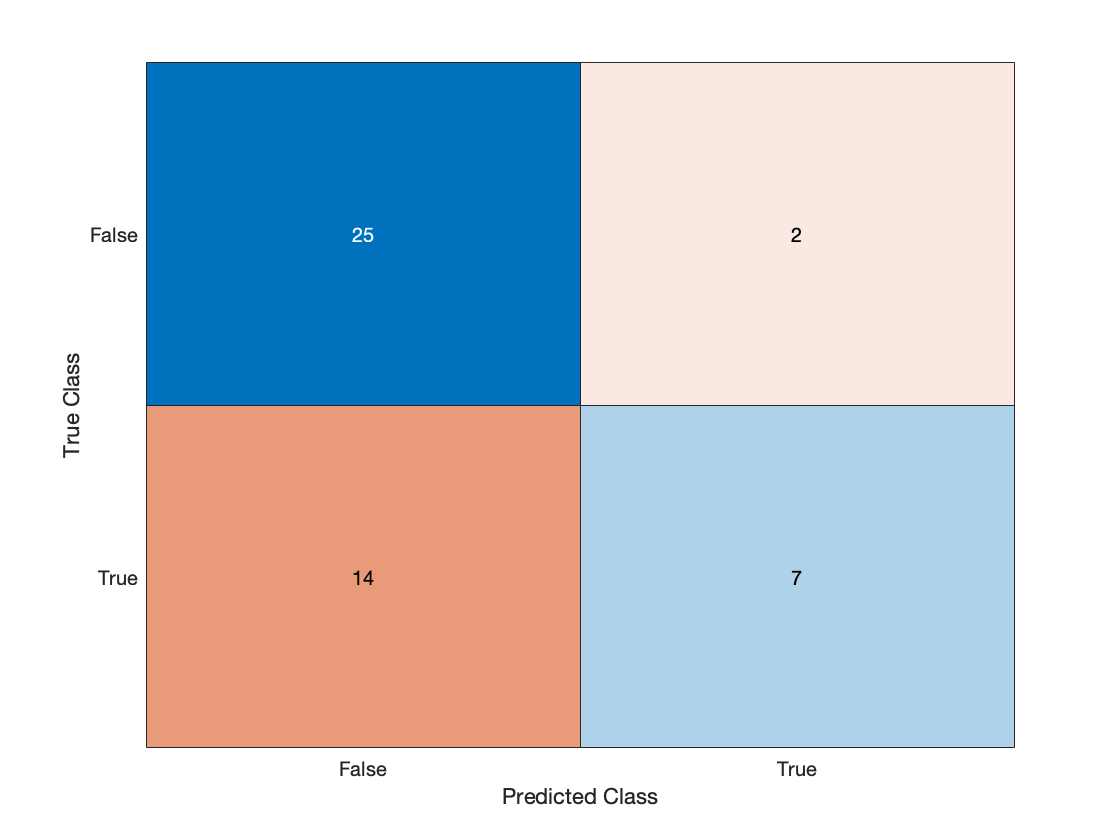

cm =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 categorical]

  Show all properties



figure('Name','Confusion Chart');
cm =confusionchart(YTest,YPred)



TN = cm.NormalizedValues(1,1);
TP= cm.NormalizedValues(2,2);
FP =cm.NormalizedValues(1,2);
FN =cm.NormalizedValues(2,1);
Total = TN +TP+FP+FN;
accuracy =(TP+TN)/Total

accuracy = 0.6667



TPR = TP/(FN+TP);
TNR = TN/(TN+FP);
FPR = FP/(TN+FP);
Presion = TP/(TP+FP)

Presion = 0.7778

Recall = TP/(TP+FN)

Recall = 0.3333

f1_pres = 1/Presion;
f1_recall = 1/Recall;
F1 = 2*(1/(f1_pres + f1_recall))

F1 = 0.4667

%https://towardsdatascience.com/the-3-most-important-composite-classification-metrics-b1f2d886dc7b
balanced_accuracy = (TPR+ TNR)/2

balanced_accuracy = 0.6296

actual = YTest =='True';
pred = YPred =='True';
[X,Y,T,AUC,OPTROCPT] = perfcurve(double(actual),double(pred),1);
AUC

AUC = 0.6296

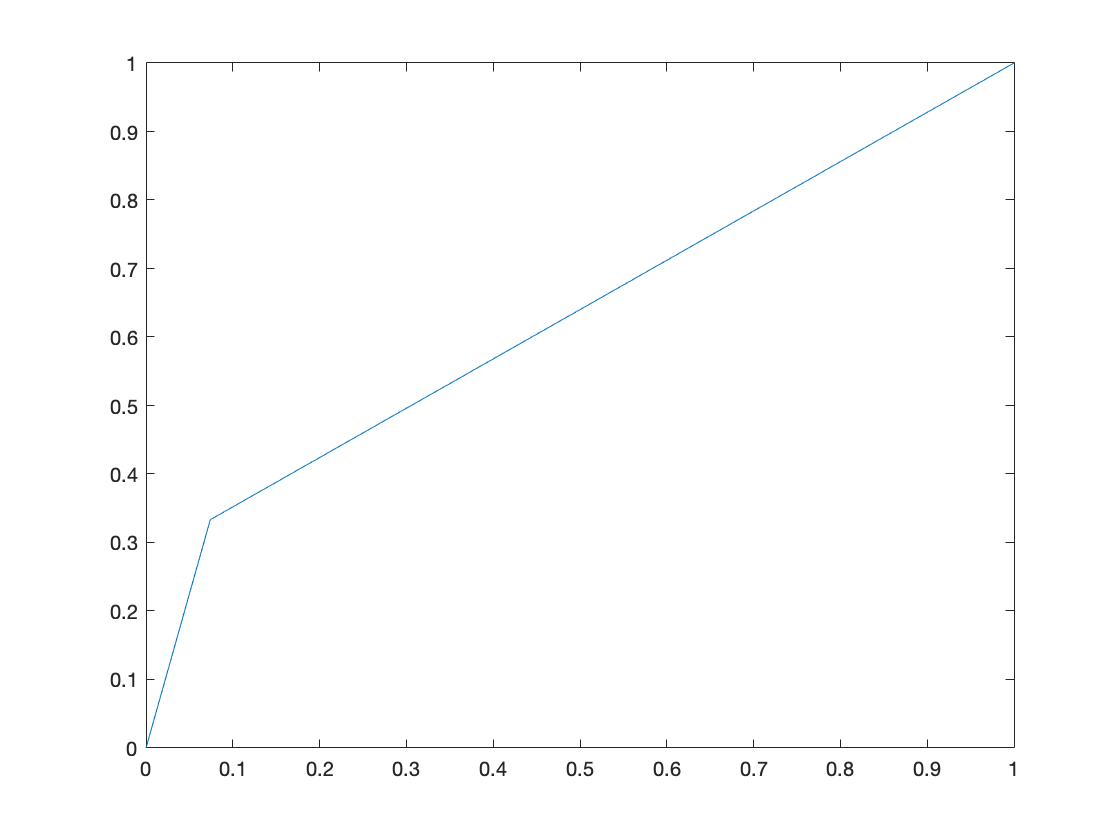


plot(X,Y)

num = TP*TN-FP*FN;
denom = (TP+FP)*(TP+FN)*(TN+FP)*(TN+FN);
MCC = num / sqrt(denom)

MCC = 0.3295

## Statistics

% col_av_cell = {};
% a = length(XTrainData{1});
% for i=1:a
%     col_av_cell{i,1} = cellfun(@(x) x(i,:), XTrainData, 'UniformOutput',false);
% end
% col_av = cell2mat(col_av_cell);

## PCA

% [COEFF, SCORE, LATENT, TSQUARED, EXPLAINED] = pca(bark1);
% reducedDimension = COEFF(:,1:5);
% reducedFeatureMatrix = bark1 * reducedDimension;
% 
% figure('Name','EigenVectors','NumberTitle','off');
% bar(COEFF);
% 
% plotpca={'f1','f2','f3','f4','f5'};
% for p=1:5
%     figure('Name',plotpca{p},'NumberTitle','off');
% 
%     score_length = size_(SCORE, 1);
%     tx_vect= SCORE(1:score_length, p);
%     scatter(1:score_length,tx_vect,'r')
%     xlabel('Timestamp in order') 
%     ylabel("Feature Values("+ plotpca{p}+")")
% end
% 
% scatter3(SCORE(:,1),SCORE(:,2),SCORE(:,3));
% 
% figure();
% pareto(LATENT);
% title('Variance Distribution')
% 
% figure();
% pareto(EXPLAINED);
% title('Percentage of Variance Explained');